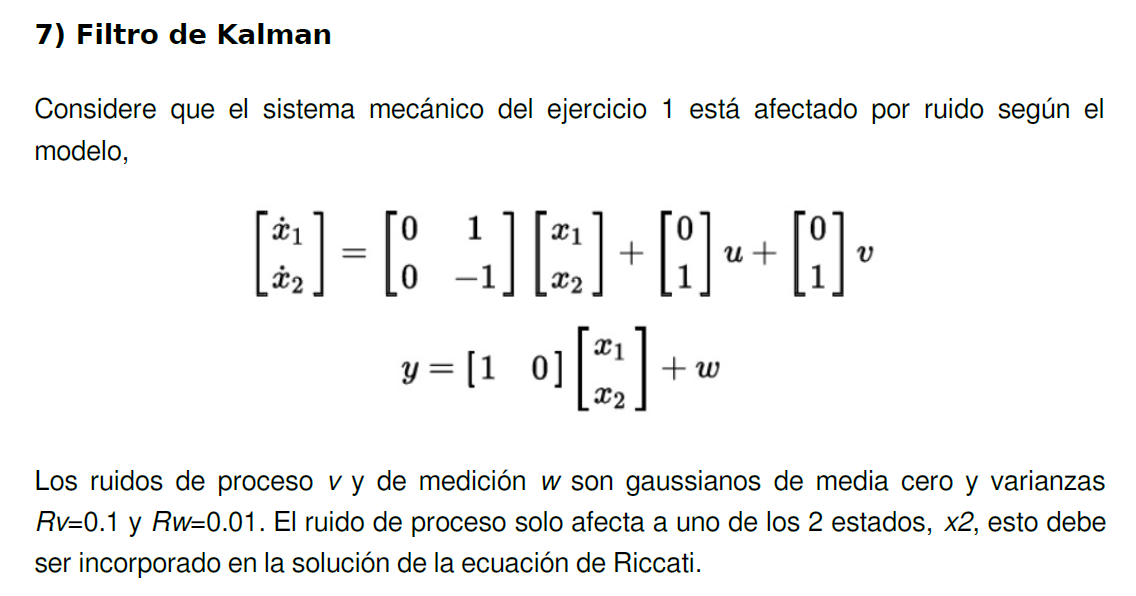

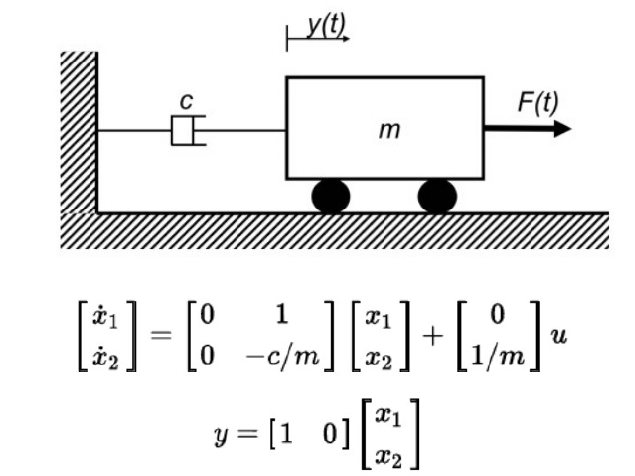

A=[0  1;
   0 -1];

C=[1 0];

Rv=0.1*[0 0;
       0 1];

Rw=0.01;


                        

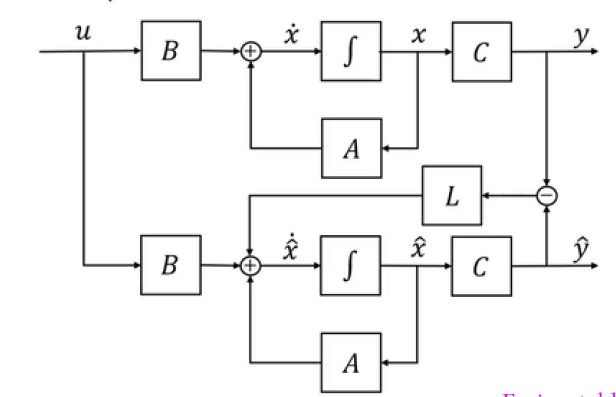

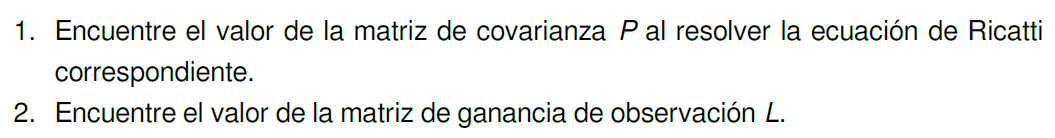

Al resolver la ec de Ricatti buscamos minimizar P y así encontramos el L óptimo que lo logra.

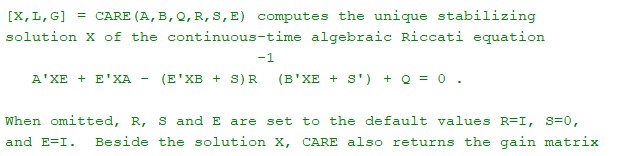

Haciendo E=I y S=0 se obtienen las siguientes correspondencias entre las ecuaciones de Riccati d la función care y del filtro de Kalman

A->A'

B->C'

X->Px

Q->Rv

R->Rw

[P,E,L]=care(A',C',Rv,Rw);
P

P =     0.0171    0.0146
    0.0146    0.0394


L

L =     1.7064    1.4559


Rv=4*Rv;
[P,E,L]=care(A',C',Rv,Rw);
P

P =     0.0269    0.0363
    0.0363    0.1341


L

L =     2.6945    3.6301



$$\left\lbrack \begin{array}{cc}
s & 0\\
0 & s
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
0 & 1\\
0 & -1
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\mathrm{L1}\\
\mathrm{L2}
\end{array}\right\rbrack *\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
s & -1\\
0 & s+1
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
\mathrm{L1} & 0\\
\mathrm{L2} & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
s+\mathrm{L1} & -1\\
\mathrm{L2} & s+1
\end{array}\right\rbrack$$


$\left|\left\lbrack \begin{array}{cc}
s+\mathrm{L1} & -1\\
\mathrm{L2} & s+1
\end{array}\right\rbrack \right|=\left(s+\mathrm{L1}\right)\left(s+1\right)+\mathrm{L2}=s^2 +\left(\mathrm{L1}+1\right)s+\mathrm{L1}+\mathrm{L2}$        (1)

$\left(s+p_1 \right)\left(s+p_2 \right)=s^2 +\left(p_1 +p_2 \right)s+p_1 p_2$        (2)

Los polos p salen sumando en s porque en realidad están en semieje negativo.

Al aumentar L1 y L2 es intuitivo viendo (1) y (2) que aumentará el valor de p1 y de p2.

Por esto se concluye que el estimador será más rápido. (Tener un L mayor magnifica el efecto del error, que se corrige más rápido)